clear 
clc

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 100E6;                     % sample rate
wt = [101, 249, 499] / 1024;     
Fin = wt .* Fs;                 % input frequency (Hz)
Ron0 = 6.5/4;                     % On-Resistance (ohm)
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-1.15, -0.15, 0.15, 0.3, 0.4, 0.6, 0.68];

getHD_new(Ron0*1.8/db2mag(-1.7), V0, C1/8, Fin(3), alpha(1))

ans =  -105.5021 -107.5281


%SD Exchange effect


Cb = 20;
Cp1 = 3;
Cp2 = 3;
Cp3 = 3;
VTH = 0.48

VTH = 0.4800

Ctot = Cb + Cp1 + Cp2 + Cp3;
% Vgs0 = [Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18] / Ctot
Vgs1 = V0* Cp1/Ctot;
mag2db(Vgs1)

ans = -19.9306

Vgs0 = (Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18) / Ctot

Vgs0 = 1.0167

mag2db(Vgs0)

ans = 0.1441

% Vgs0 = db2mag(0.71)
Ron = Ron0*(1.8-VTH)/(Vgs0-VTH)

Ron = 3.9965

% Ron = db2mag(7.5)
mag2db(Ron)

ans = 12.0335

R2 = ((Vgs1 / (Vgs0-VTH))^2)* Ron / 2

R2 = 0.0705

mag2db(R2)

ans = -23.0383

mag2db(R2*(C1/8)*Fin(3)*pi*V0)

ans = -86.6059

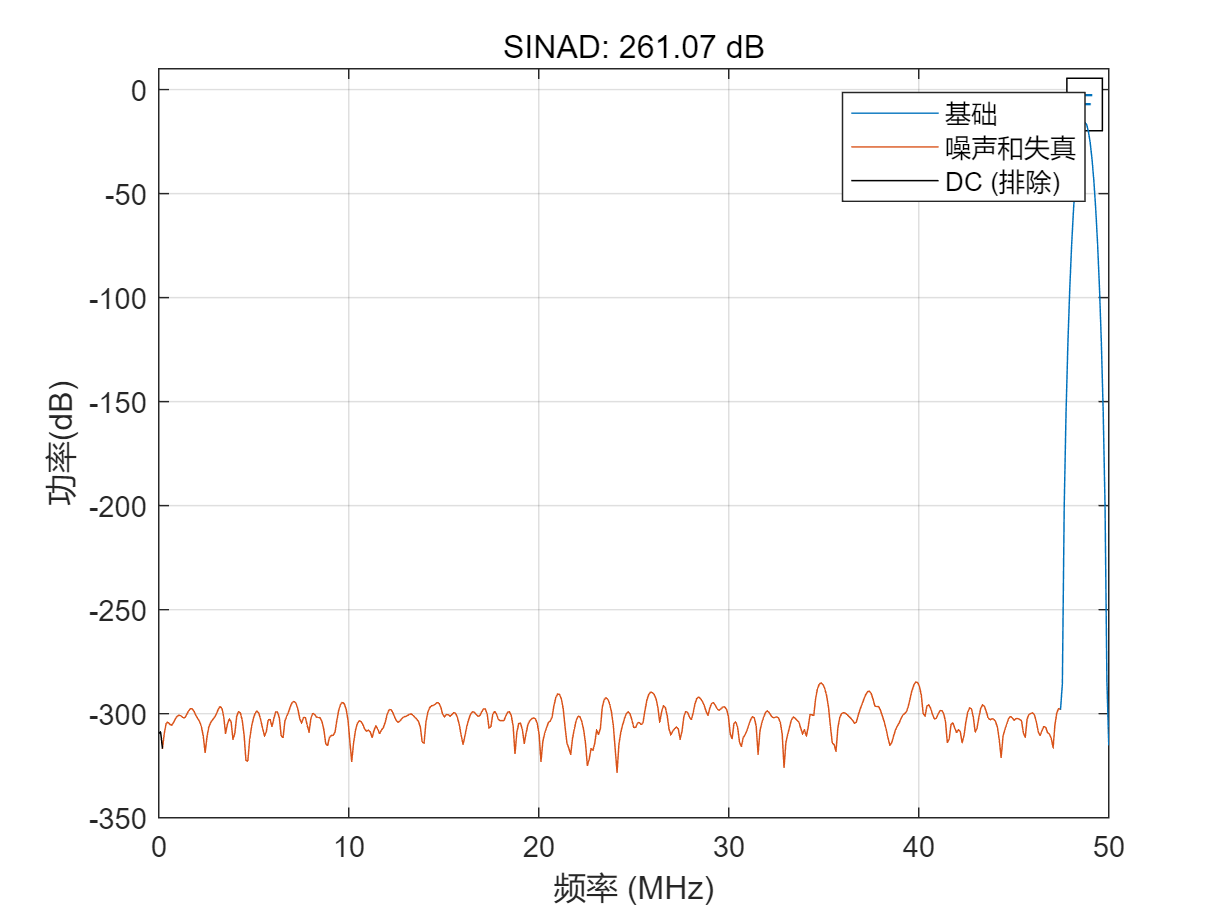

ans = 261.0679

t = 0:1/Fs:1/Fs*1023;
omega = 2*pi*Fin(3);
Vgs = Vgs0 + Vgs1*sin(omega*t);
sinad(Vgs, Fs)

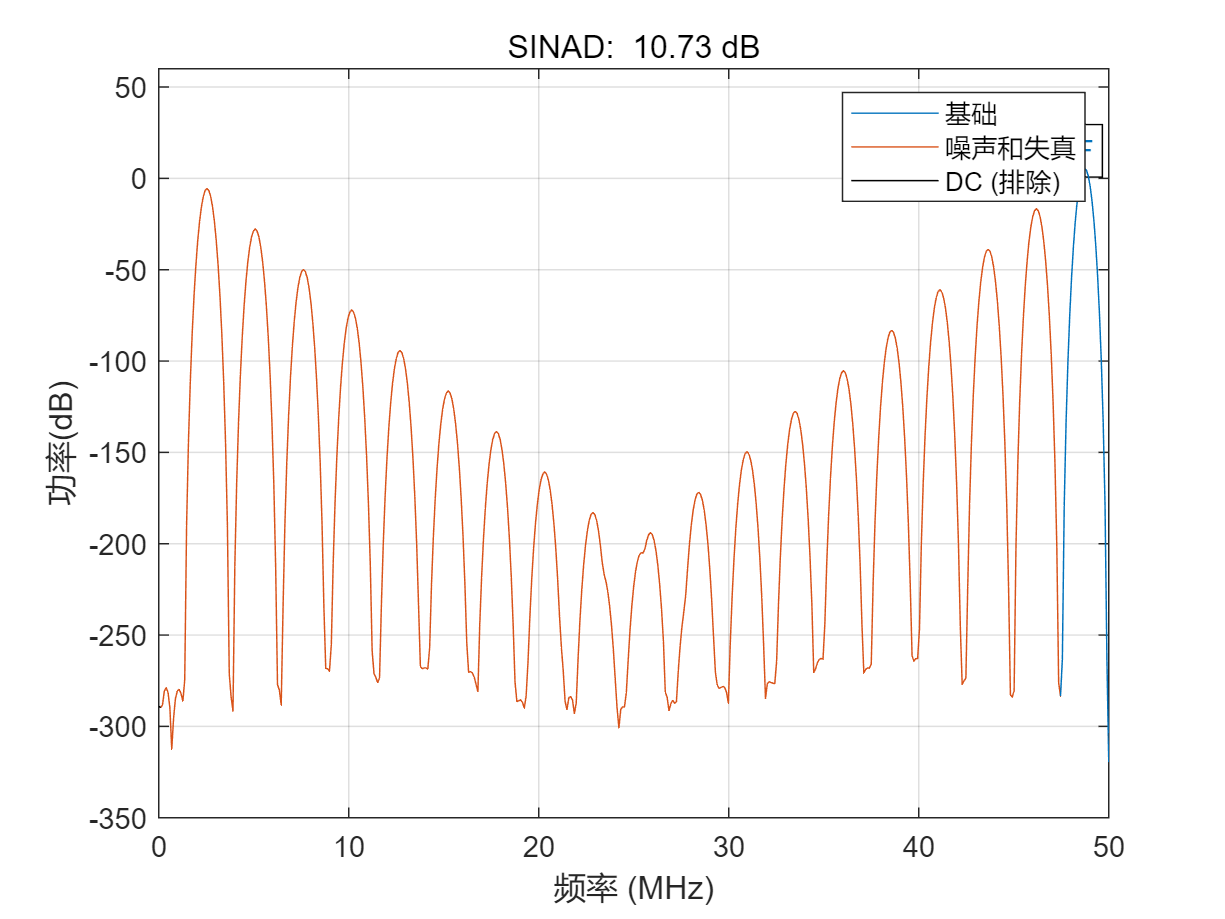

ans = 10.7309

Ron = 1./(Vgs - 0.45) / (280E-6 * 32*12/0.2);
sinad(Ron,Fs)

[~, harmfreq, harmpower]= thd(Ron,Fs, 5)

harmfreq =     5.5191
       NaN
       NaN
       NaN
       NaN


harmpower = 	1.0e+07 *

    4.8730
       NaN
       NaN
       NaN
       NaN
